# **Proof of Concept**

**Notes: **It needs Yalmip and OSQP. Yalmip should install himself automatically both on Windows and Linux. OSQP should automatically install on Linux, if there are any problems read the README. On Windows you need to install OSQP yourself.

There are TONs of other parameters and configuration you can tune and adapt, but atm you need to search them yourself.

clc;
clear variables;
terminate(pyenv)
%pyenv(Version='/scratch/msc23h12/python/bin/python3',ExecutionMode='OutOfProcess');

## **Initialization HPC 7x7 Problem**

%% INIT

% Instantiate main Class:
hpc = hpc_lab;

MAY be NOT Observable!
Size: 54800 bytes


% Rows and Columns
hpc.Nv = 10;

[TM] Remember to change Nh, epos, and the floorplan accordingly


hpc.Nh = 10;

[TM] Remember to change Nv, epos, and the floorplan accordingly



% Core number
hpc.Nc = hpc.Nh*hpc.Nv;

[TM] Remember to change Nh, Nv, epos, the parameter deviation vector, and the floorplan accordingly



% Number of Voltage Domains
hpc.vd = hpc.Nc;

% How the cores are distributed per domain
%hpc.VDom = ... ;
% Alternatively
hpc.default_VDom_config();

% Default Floorplan and Parameter deviation vector
hpc.default_floorplan_config();
hpc.create_model_deviation();

%Decide simulation frequency (discrete timing)
hpc.Ts = 5e-5;

%Decide total simulation time
hpc.tsim = 1;

%Presence/Absence of sensor noise:
hpc.sensor_noise = 1;

%Thermal model version
hpc.model_ver = 0;

#### After the configuration of the Thermal Model, run the model creation & others

hpc.model_init();

MAY be NOT Observable!


hpc.create_core_pw_noise();

#### Choose targets

% Initial Temperature condition
hpc.t_init = hpc.temp_amb*ones(hpc.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc = 3.45 * ones(tt, hpc.Nc);

%Target Power Budget
hpc.tot_pw_budget = 450/36*hpc.Nc*ones(tt,1);
tu = ceil(tt/4);
hpc.tot_pw_budget(tu+1:2*tu) = 2*hpc.Nc;
hpc.tot_pw_budget(2*tu+1:3*tu) = 5*hpc.Nc;
hpc.tot_pw_budget(3*tu+1:3*tu+ceil(tu/2)) = 3*hpc.Nc;
hpc.tot_pw_budget(3*tu+ceil(tu/2)+1:end) = 8*hpc.Nc;
hpc.quad_pw_budget = 450/36*hpc.Nc*ones(2,hpc.vd);

%Others, TODO
hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

hpc.anteSimCheckTM();
hpc.anteSimCheckLab();
hpc.anteSimCheckPM();

### **Generate Workload trace:**

%Probability of each workload type [idle, int, float, mem, vec]
hpc.wl_prob = [0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
hpc.wl_min_exec_us = [510 100 100 480 520];

%Mean execution time (us) of each workload type
hpc.wl_mean_exec_us = [520e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc = hpc.generate_wl_trace(hpc.Nc, hpc.tsim, 0);

## **CP MPC - sparsified**

ctrl2 = cp_mpc;
ctrl2.save_solver_stats = false;
ctrl2.C = eye(hpc.Ns);

% osqp settings
set = osqp.default_settings;
set.warm_start = false;
set.verbose = false;

%set.rho = 0.1;
%set.eps_abs = 0.001; %0.01
%set.eps_rel = 0.0001; %0.01
set.check_termination = 0;
set.max_iter = 10;
ctrl2.ops = set;

%Controller frequency (s)
ctrl2.Ts_ctrl = 1e-3;
ctrl2.Nhzn = 2;

%Robust Margins for T and P
ctrl2.Cty = zeros(ctrl2.Nhzn, hpc.Nc);
ctrl2.Ctu = zeros(ctrl2.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl2.R = R_coeff*eye(hpc.Nc);

%Others
ctrl2.R2 = zeros(hpc.Nc);
ctrl2.Q = zeros(hpc.Ns);

% discretize
ctrl2 = ctrl2.init_fnc(hpc, 0);

Optimizer object with 306 inputs (4 blocks) and 304 outputs (2 blocks). Solver: OSQP


neg_vals_in_Adctrl = sum(ctrl2.Ad_ctrl(:) < 0)

neg_vals_in_Adctrl = 0

nnzA = nnz(ctrl2.Ad_ctrl)

nnzA = 41616

neg_vals_in_Bdctrl = sum(ctrl2.Bd_ctrl(:) < 0)

neg_vals_in_Bdctrl = 0

nnzB = nnz(ctrl2.Bd_ctrl)

nnzB = 20604

## Explore cutoff

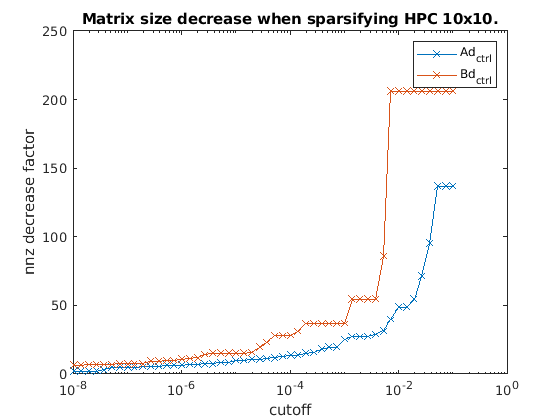

cutoff = logspace(-8,-1);
spupA = zeros(length(cutoff),1);
spupB = zeros(length(cutoff),1);
for i= 1:length(cutoff)
    sizeA = nnz(ctrl2.Ad_ctrl > cutoff(i));
    spupA(i) = nnzA/sizeA;
    sizeB = nnz(ctrl2.Bd_ctrl > cutoff(i));
    spupB(i) = nnzB/sizeB;
end

figure();
semilogx(cutoff,spupA,'-x');
xlabel('cutoff');
ylabel('nnz decrease factor')
title(sprintf('Matrix size decrease when sparsifying HPC %dx%d.',hpc.Nh,hpc.Nv))
hold on;
semilogx(cutoff,spupB,'-x');
legend('Ad_{ctrl}','Bd_{ctrl}');

## sparsify

sparsifying A by x31.432024.  nnz(A) goes from 41616 to 1324.
sparsifying B by x78.045455.  nnz(B) goes from 20604 to 264.
Optimizer object with 306 inputs (4 blocks) and 304 outputs (2 blocks). Solver: OSQP


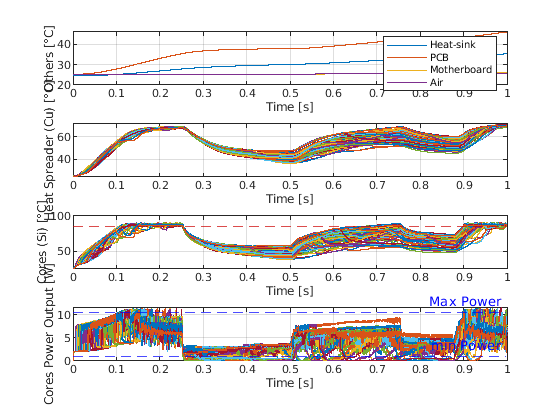

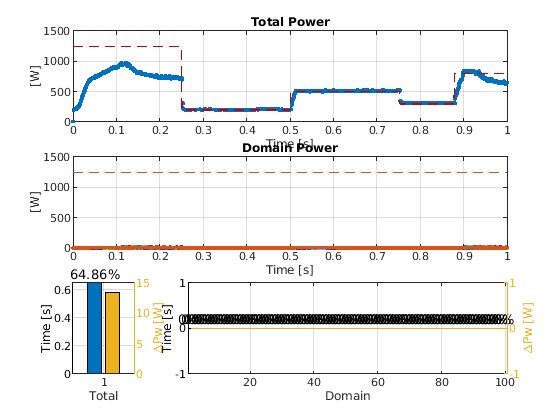

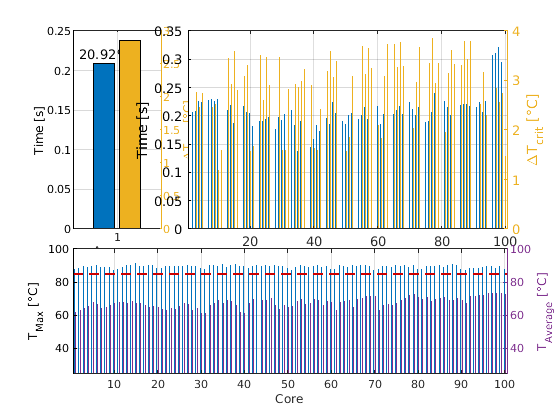

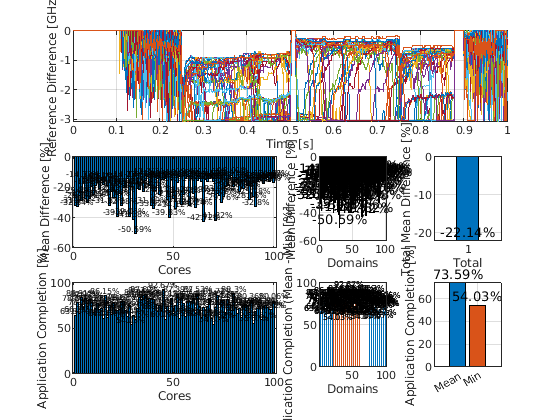

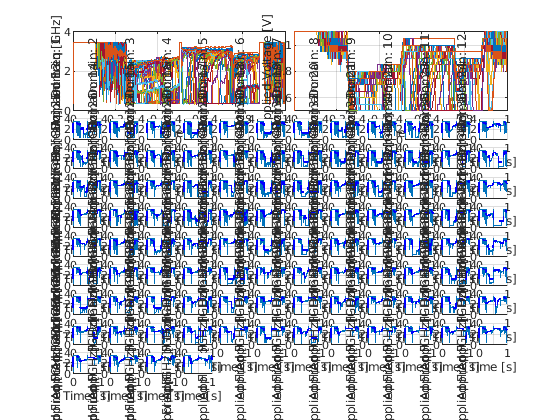

[CTRL][MPC] number of times the optimization algorithm failed:0/1000


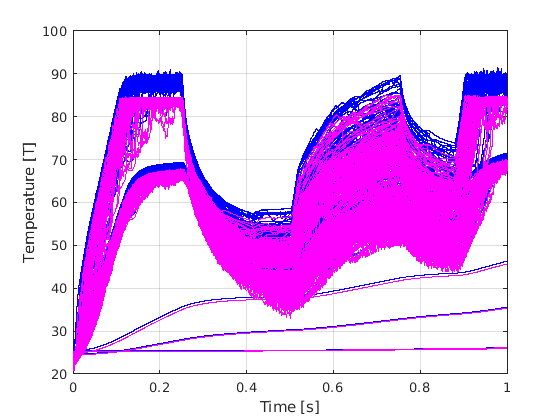

ctrl2.cutoffA = 5e-3;
ctrl2.cutoffB = 5e-3;

%Launch Simulation
tic;
hpc.simulation(ctrl2,1);

toc;

Elapsed time is 97.613949 seconds.


## **CP MPC - original**

ctrl = cp_mpc;
ctrl.save_solver_stats = false;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;
ctrl.Nhzn = 2;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
ctrl.R2 = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

%Launch Simulation
tic;
hpc.simulation(ctrl,1);
toc;

## Run Checks and Optain Metrics

% get primal variables from optimizer
prim = [ctrl.solver_stats.prim];
dual = [ctrl.solver_stats.dua];

pusum = prim(end,:);

u0ap = [ctrl.solver_stats.u0];
usum = [ctrl.solver_stats.usum];
uref = [ctrl.solver_stats.uref];
info = [ctrl.solver_stats.info];
lin  = [ctrl.solver_stats.lin];%set.check_termination = 0;

uin  = [ctrl.solver_stats.uin];
iter = [info.iter];
pri_res = [info.pri_res];
dua_res = [info.dua_res];

% average primal and dual residual
mean(pri_res)
mean(dua_res)

% average rho estimate
rho_estimate = [info.rho_estimate];
mean(rho_estimate)
min(rho_estimate)
max(rho_estimate)
mean(iter)
min(iter)
max(iter)